# Wyznaczanie konturów obiektów

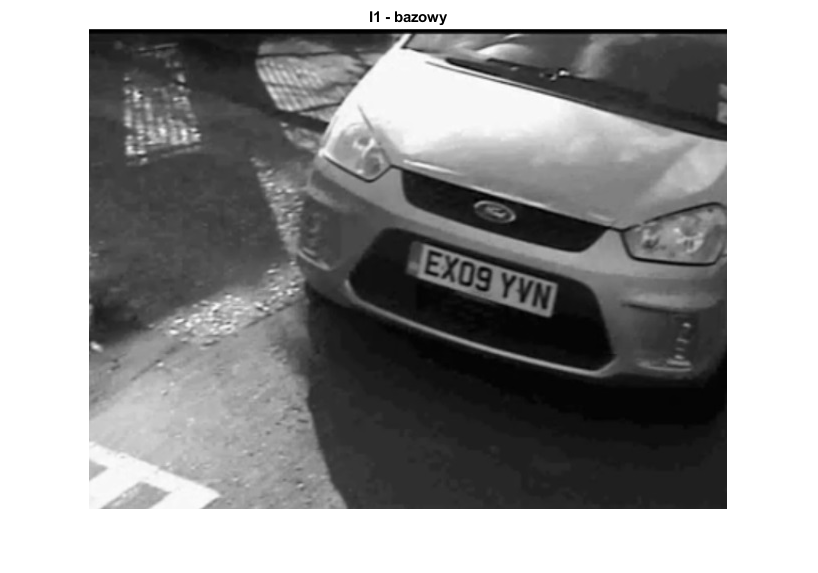

I = imread('car1.jpg');

I1 =  double(rgb2gray(I));
figure; imshow(I1,[]); title('I1 - bazowy')

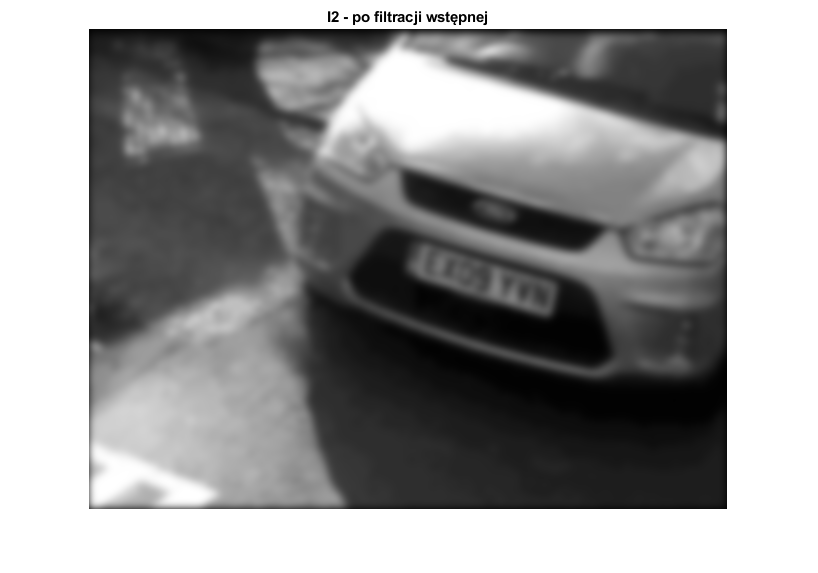

%----- filtracja wstępna:generowanie maski filtru Gaussa lub innego filtru
h = fspecial('gaussian', 32,4); % generowanie maski filtru Gaussa...
% h = [];  % generowanie maski innego filtru...
I2 = imfilter(I1, h); figure;imshow(I2,[]);title('I2 - po filtracji wstępnej')

% I2 = quant(I2,1); % kwantyzacja po filtracji [0 255]

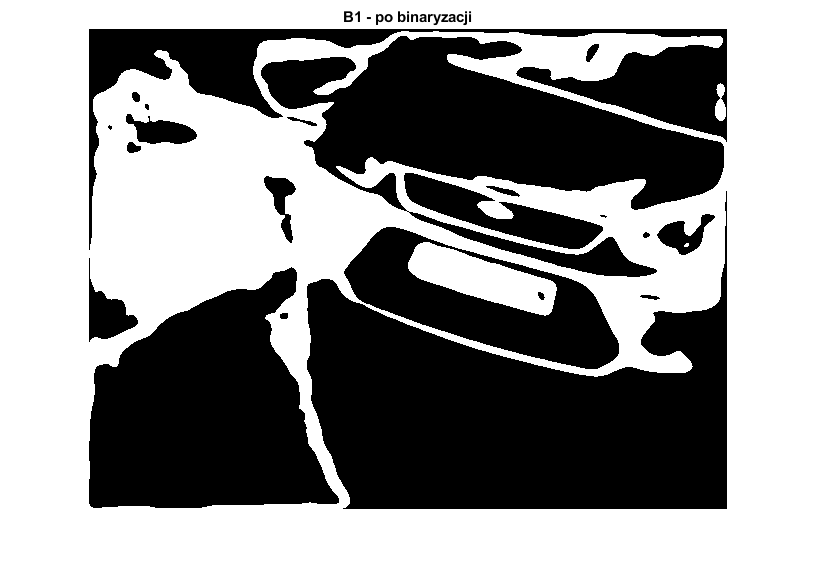

%imcontrast(imshow(I2))


lt =   60;      % dolny prog binaryzacji
ut =   130;     % gorny prog binaryzacji

% ----- binaryzacja -------
B1 = I2; 
B1(B1<lt)=0; % usunięcie pikseli o wartościach mniejszych od lt 
B1(B1>ut)=0; % usunięcie pikseli o wartościach większych od ut 
B1(B1>0) = 1; % przypisanie pozostałym o wartościom 1
figure;imshow(B1,[]);title('B1 - po binaryzacji')

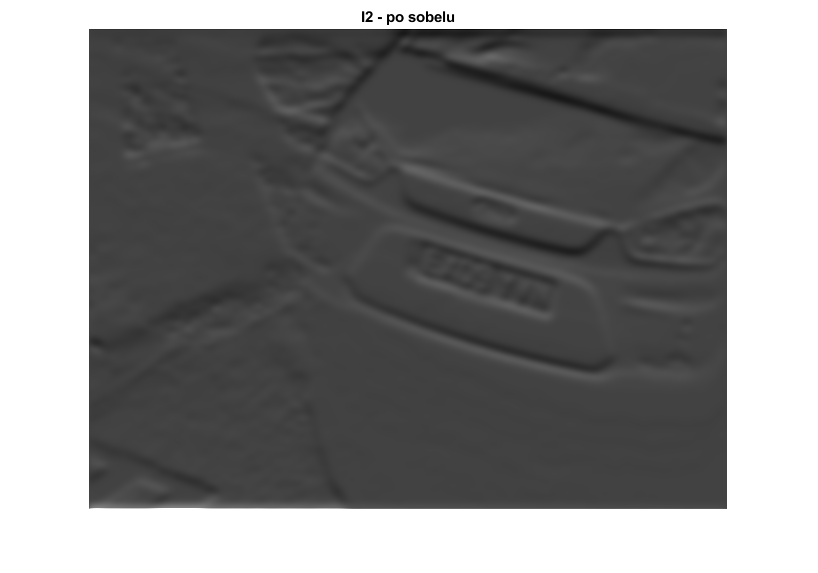


H_fspec_sob = fspecial('sobel');
H_fspec_prew = fspecial('prewitt');

I_fspec_sob = imfilter(I2, H_fspec_sob); 
figure;imshow(I_fspec_sob,[]);title('I2 - po sobelu')

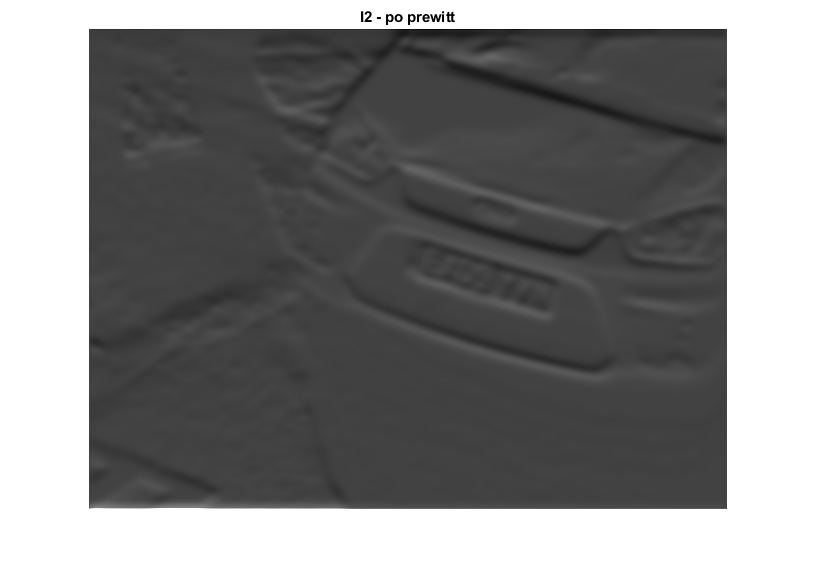


I_fspec_prew = imfilter(I2, H_fspec_prew); 
figure;imshow(I_fspec_prew,[]);title('I2 - po prewitt')

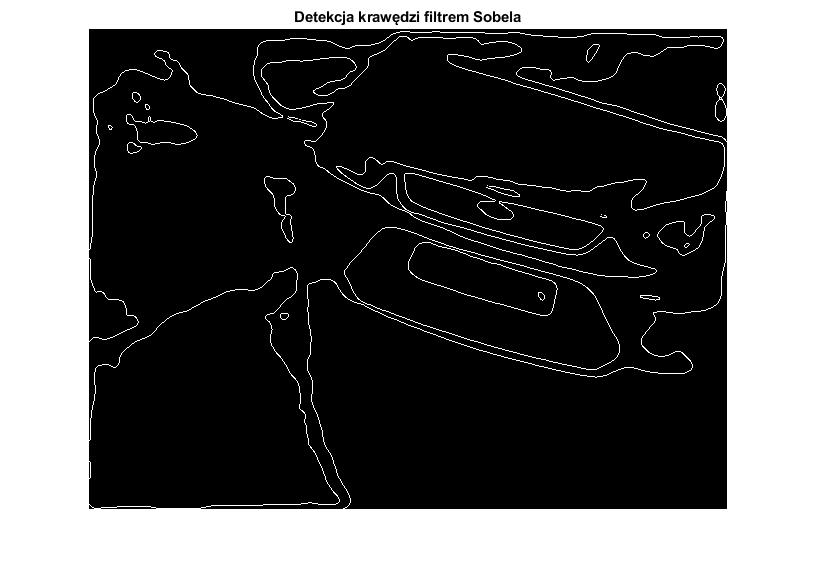


Isob = edge(B1,'sobel'); figure; imshow(Isob,[]); title('Detekcja krawędzi filtrem Sobela')